# Praktikum 4 - Shift 1 Selasa

`12 Oktober 2021`

`Nama : ``Asisten Praktikum`

`NIM  :`

## Nomor 1

Tuliskan kelebihan polinom interpolasi Newton dibanding interpolasi Lagrange !

#### **Jawaban :**

Karena kita menyimpan hasil tabel beda terbagi, maka kita dapat merekam dan membandingkan hasil interpolasi pada setiap orde, sehingga memungkinkan kita untuk melakukan evaluasi terhadap "fit" dari interpolasi dengan mudah. Di sisi lain, untuk melakukan ini dengan metode Lagrange mengharuskan kita untuk mengulangi prosedur yang sama dari awal.

## Nomor 2

Bangunlah suatu fungsi `polinom_newton.m` yang menerima input array $X=[x_0, x_1, x_2, ..., x_n]$ dan $Y=[y_0, y_1, y_2, ..., y_n]$ dimana $f(x_i)=y_i$ untuk $1\leq i\leq n$  yang menghasilkan keluaran $p_n(x)$, polinom interpolasi Newton orde $n$ yang melalui semua titik $((x_0, f(x_0)), (x_1, f(x_1)), ..., (x_n, f(x_n))$.

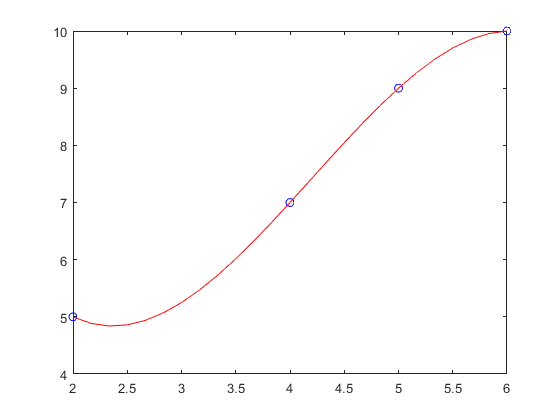

% Run section ini untuk memeriksa jawaban anda!
X = [2,6,5,4];
Y = [5,10,9,7];
X1 = linspace(2,6,25);
f = polinom_newton(X,Y);
plot(X,Y,'bo', X1, f(X1), 'r-')

## Nomor 3

Diketahui suatu objek dilempar ke atas dengan kecepatan awal $v_0$. Ternyata, ketinggian objek tersebut setiap saat dapat digambarkan oleh persamaan

### 
$$z(t)=z_0 + \frac{m}{c}\left(v_0+\frac{mg}{c} \right) (1-e^{-(c/m)t})-\frac{mg}{c}t$$


dengan 

- $z=$ ketinggian (m) diatas permukaan tanah

- $z_0=$ketinggian awal (m)

- $m=$massa objek (kg)

- $c=$koefisien *drag *(kg/s)

- $v_0=$kecepatan awal (m/s)

- $t=$ waktu (s)

Dilakukan eksperimen sebagai berikut: Objek seberat 900 gram dilempar ke atas dari ketinggian awal 75 meter diatas permukaan tanah, dengan kecepatan awal 10 m/s. Diketahui bahwa objek tersebut memiliki koefisien drag $c=$150 gram/s. Asumsikan $g=$9.81 m/s^2. Ketinggian benda diukur dari awal pelemparan ($t=0$) sampai $t=5$ sekon. 

Ternyata, sensor tersebut mengalami kerusakan. Ketinggian benda hanya terukur ketika $t=0$, $t=2$, $t=4$, dan $t=5$ sekon. 

Diperoleh data sebagai berikut:

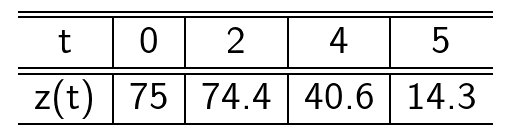

### 3A

Bangun polinom Interpolasi Newton orde 3 $p_3(t)$ menggunakan data yang diperoleh dari sensor !

T = [0,2,4,5];
Z_T = [75, 74.4, 40.6, 14.3];
p_3 = polinom_newton(T, Z_T);

### 3B

Plot grafik polinom Interpolasi Newton orde 3 $p_3(t)$yang sudah diperoleh dari bagian $3A$ untuk $t\in [0,5]$, bersama dengan plot $z(t)$. Apa yang dapat kamu simpulkan dari grafik tersebut?

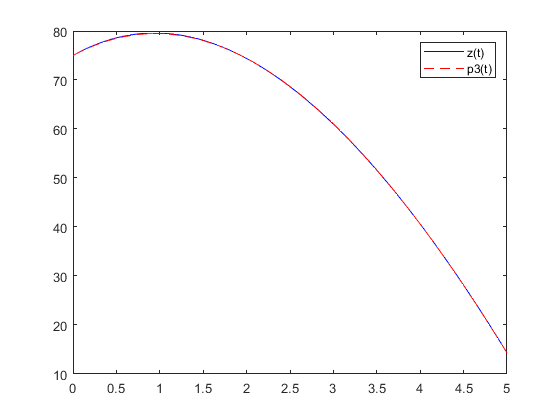

c = 0.15;
g = 9.81;
z_0 = 75;
m = 0.9;
v_0 = 10;
z  = @(t) z_0 + m*(v_0 + m*g./c)*(1-exp(-c*t./m))./c-m*g*t./c;
t = linspace(0,5,100);
plot(t,z(t), 'b-', t, p_3(t), 'r--')
legend('z(t)', 'p3(t)')